#### *Preamble*

close all
clear all
clc

## VARIABLES

Fluid = "127";             % Select fliud
Metal = "18";             % Select metal      
WICK_TYPE = "sintered";         % Select Wick Type

## HEAT PIPE PROPERTIES 

HP_Length = 500;         % Heat Pipe Length, mm
COND_Length = 100;       % Condenser Length, mm
EVAP_Length = 100;       % Evaporator Length, mm
HP_Angle = 0;          % Operating Angle, °
OP_Temp = 100;           % Operationg Temeprature, °C
HP_Diameter = 25.4;       % Heat pipe diameter, mm
T_WALL = 3.3;            % Wall Thickness, mm
OPRATING_POWER = 150;    % Nominal operating power for dT estimates, W

## WICK PROPERTIES 

### *Mesh*

Mesh_material = "PhosB";     % Select Wick Material
N_WRAPS = 8;           % Number of Wraps, #
MESH_NUMBER = 200;       % Mesh Number, gaps p/ inch
D_WIRE = 0.0000625;            % Wire diamter, m
WICK_K = 50;            % Wick Thermal Conductivity, W/mK - Phosphorus Bronze = 386.4

### *Sinter*

SINTER_D = 0.1;          % Sinter Diameter, mm
MAND = 0;              % Mandrel Diameter, mm (set as 0 for optimal mandrel diameter)

## OTHER PROPERTIES

Contact_Angle = 0;     % Contact angle (deg) between fluid and metal (for ideal case put 0)
GRAVITY = 9.81;           % Acceleration due to gravity, m/s2
sf = 2;                % Wall thickness safety factor
Rn = 6e-8;                % Nucleation Radius Value, m

***Mesh - advanced***

gap_mult = 1;          % Gap multiplier for mesh wicks, - ;This is used to estimate the wick thichness taking into account the space between mesh layers. The multipliyer signifies a value that the wick thickness with no gaps is multiplied by to estimate the thickness with gaps. I've used a multiplier of 2.5 in the past to better correlate to mesh wick experimental results, but it is something that needs more investigation and should be used with caustion.  

*RUN CODE*

A_1_0_0a_DATA_EXTRACTION

Tmin = 0

Tmax = 374

B_1_0_0a_VARIABLE_DEFINITION

Min_wall_thickness_mm = -2.2949e-05

Maximum_Capilary_Rise_m = 0.7267

WICK_TYPE = "sintered"

Optimal_mandrel_diameter_mm = 2.9000

Fill_Volume_cc = 68.9409

Fill_Mass_g = 65.8806

NAME_FLUID = "WATER"

NAME_METAL = "Cu"

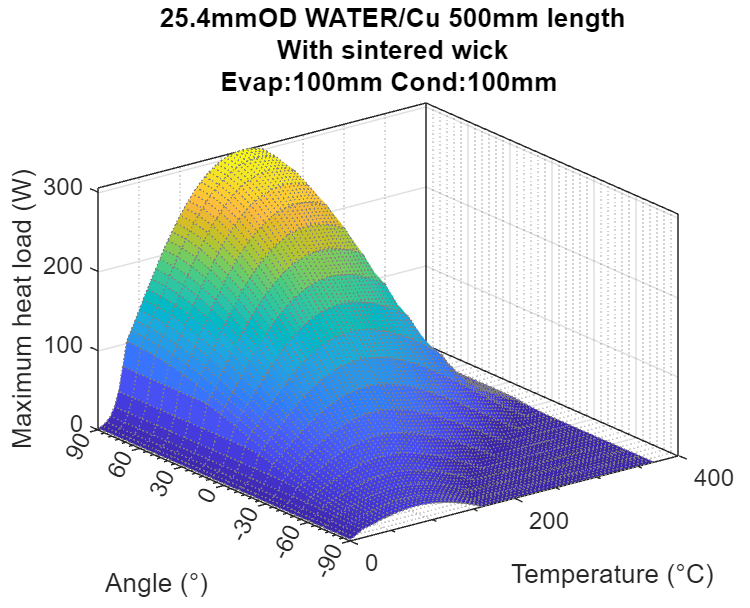

C_1_0_0a_CALCULATIONS
D_1_0_0a_dT_calc
G1_1_0_0a_Graph_1       % 3D plot

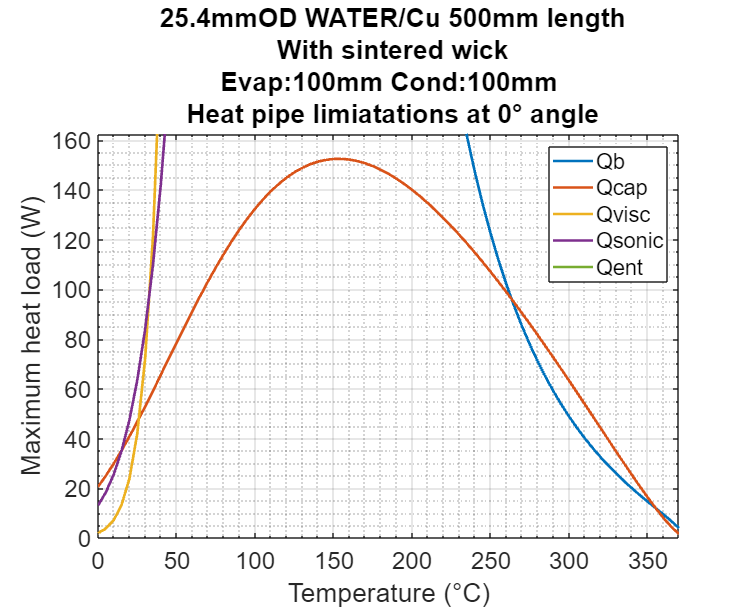

G2_1_0_0a_Graph_2       % All limits 

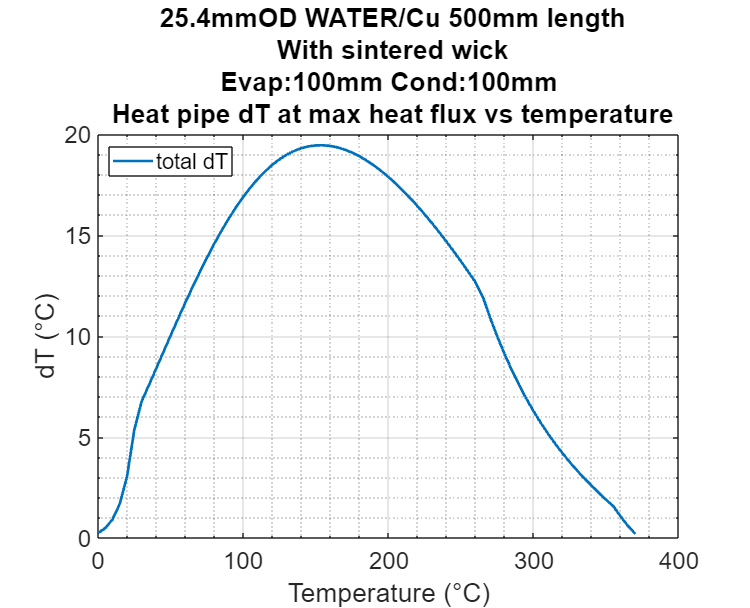

G3_1_0_0a_Graph_3       % dT 

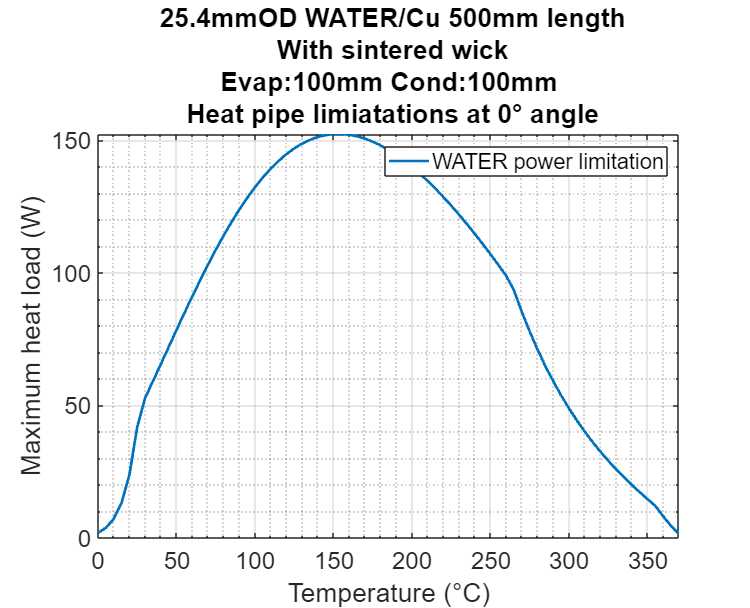

G4_1_0_0a_Graph_4       % Performance curve  

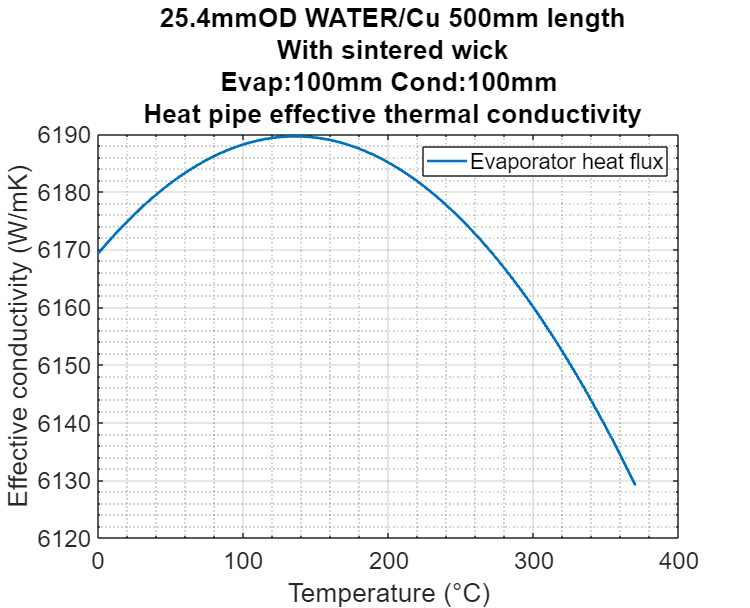

G5_1_0_0a_Graph_5       % Effective K

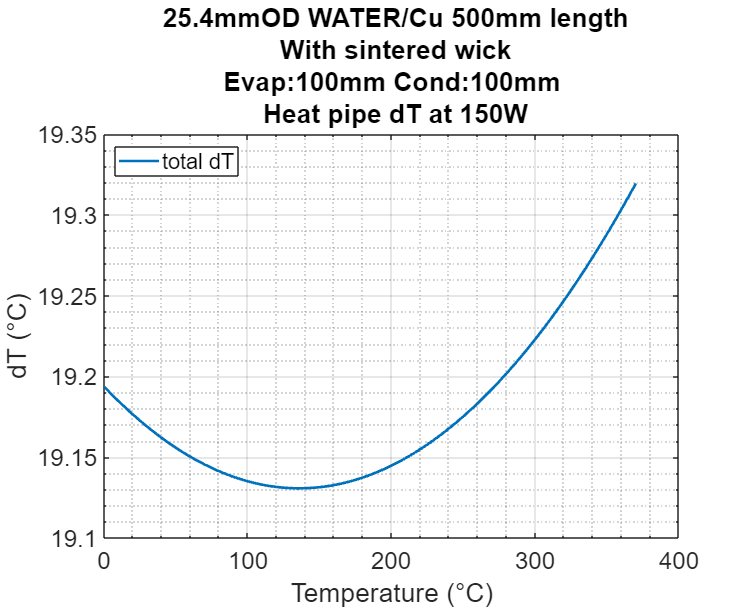

% G6_1_0_0a_Graph_6     % Thermal resistance
% G7_1_0_0a_Graph_7     % Heat fluxes
% G8_1_0_0a_Graph_8     % Angle comparison
% G9_1_0_0a_Graph_9     % Nucleation radius
% G10_1_0_0a_Graph_10   % Reynolds
% G11_1_0_0a_Graph_11   % Radial reynolds
G12_1_0_0a_Graph_12     % dT at fixed operating power

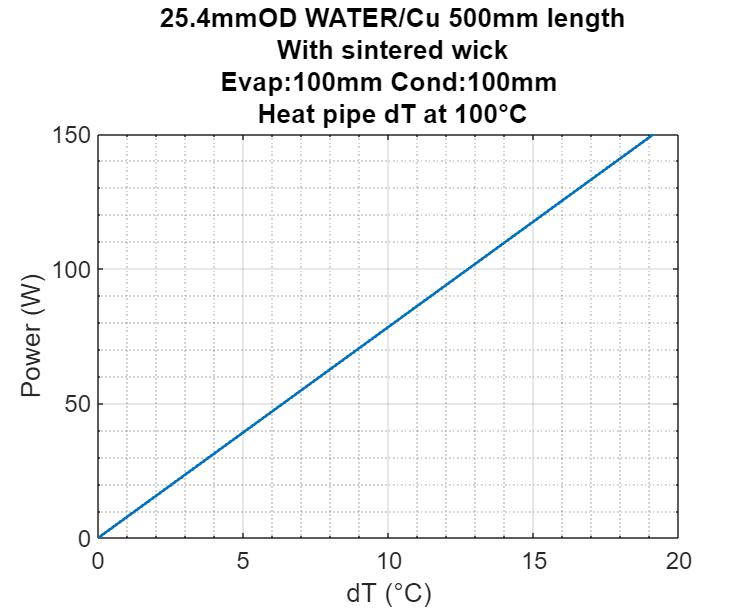

G13_1_0_0a_Graph_13     % dT at fixed temperature 

*SAVE OUTPUTS, Uncoment to save all graphs as .png*

% z4_SAVE

## Version Control

see zz_versioncontrol